
PM1 = 27:99; % Indices for time periods 
PM2 = 171:243;
PM3 = 315:387;
meanPM1=mean(PM1)

meanPM1 = 63

meanPM2=mean(PM2)

meanPM2 = 207

meanPM3=mean(PM3)

meanPM3 = 351

PMtable=[meanPM1,meanPM2,meanPM3]

PMtable =     63   207   351



AM1 = 1:26;
AM2 = 100:170;
AM3 = 244:314;
AM4 = 388:408;
meanAM2=mean(AM2)

meanAM2 = 135

meanAM3=mean(AM3)

meanAM3 = 279

AMtable=[meanAM2,meanAM3]

AMtable =    135   279



NR1 = sum(delDOdtk(PM1))/6 %mmol/m2/hr 

NR1 = -112.0017

NEP1 = sum(delDOdtk(AM2))/6 

NEP1 = 16.1336

NR2 = sum(delDOdtk(PM2))/6 %mmol/m2/hr 

NR2 = -84.5832

NEP2 = sum(delDOdtk(AM3))/6 

NEP2 = 37.0200

NR3 = sum(delDOdtk(PM3))/6 %mmol/m2/hr 

NR3 = -119.7698


NEM1 = NEP1 + NR2

NEM1 = -68.4496

NEM2 = NEP2 + NR3

NEM2 = -82.7497

NEM1Time= mean(meanAM2+meanPM2)

NEM1Time = 342

NEM2Time= mean(meanAM3+meanPM3)

NEM2Time = 630

NEMTime=[NEM1Time, NEM2Time]

NEMTime =    342   630



meanR1 = nanmean(delDOdtk(PM1))

meanR1 = -9.2056

meanR2 = nanmean(delDOdtk(PM2))

meanR2 = -6.9520

meanR3 = nanmean(delDOdtk(PM3))

meanR3 = -9.8441


DRR1 = meanR1*24

DRR1 = -220.9348

DRR2 = meanR2*24

DRR2 = -166.8490

DRR3 = meanR3*24

DRR3 = -236.2581


GPP1 = NEP1 + length(AM2)/6*abs(meanR2)

GPP1 = 98.3994

GPP2 = NEP2 + length(AM3)/6*abs(meanR3)

GPP2 = 153.5084


NEMtable=[NEM1,NEM2]

NEMtable =   -68.4496  -82.7497


GPPtable=[GPP1,GPP2]

GPPtable =    98.3994  153.5084


ERtable=[DRR1, DRR2, DRR3]

ERtable =  -220.9348 -166.8490 -236.2581


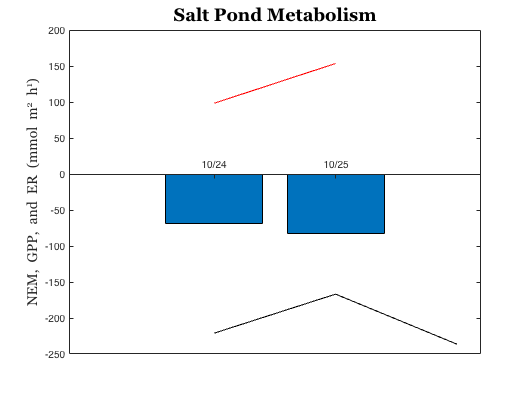


figure


ax = gca;
bar(NEMtable)
ax.XAxisLocation = 'origin';
%ax.YAxisLocation = 'origin';
hold on
plot(ERtable,'k')
hold on
plot(GPPtable,'r')
hold on
ylabel('NEM, GPP, and ER (mmol m^-^2 h^-^1)','FontName','Georgia','FontSize',14)
title('Salt Pond Metabolism','FontName','Georgia','FontSize',18)
xticks([1 2])
xticklabels({'10/24','10/25'})

%set(xticklabels,'FontName','Georgia')
%set(ax,'FontName','Georgia','XTick','XTickLabel',{'10/24','','10/25'});


